Generamos la secuencia de Gold inicial (Tx).

goldseqA = comm.GoldSequence('FirstPolynomial','x^6+x^5+x^2+1',...
    'SecondPolynomial','x^6+x^5+x^4+x^3+x^2+1',...
    'FirstInitialConditions',[1 0 1 0 1 0],...
    'SecondInitialConditions',[0 1 0 1 0 1],...
    'Index',4,'SamplesPerFrame',56,...
    'OutputDataType', 'logical');

Generamos la segunda secuencia (Rx). Esta secuencia tiene los mismos parámetros que la primera.

goldseqB = comm.GoldSequence('FirstPolynomial','x^6+x^5+x^2+1',...
    'SecondPolynomial','x^6+x^5+x^4+x^3+x^2+1',...
    'FirstInitialConditions',[1 0 1 0 1 0],...
    'SecondInitialConditions',[0 1 0 1 0 1],...
    'Index',4,'SamplesPerFrame',56,...
        'OutputDataType', 'logical');

Calculamos la correlación y generamos la gráfica

*TODO: la gráfica debería estar centrada en "Samples per frame" y negativos por un lado y positivos por otro. A lo mejor será preferible usar plot en vez de stem.*

y = xcorr(goldseqA(),goldseqB())

y =     0.0000
    1.0000
    1.0000
    2.0000
    3.0000
    3.0000
    4.0000
    3.0000
    5.0000
    4.0000


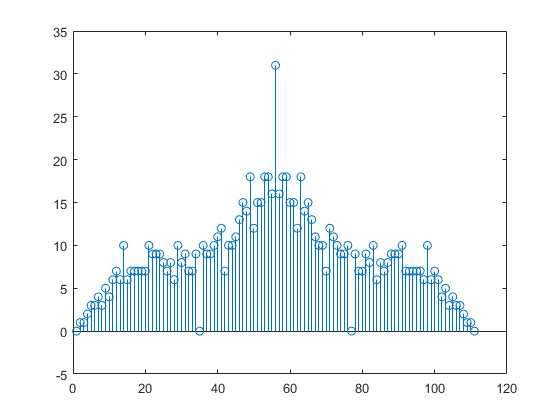

s =   Stem with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
          BaseValue: 0
              XData: [1×111 double]
              YData: [1×111 double]

  Show all properties


s=stem(y)

[maxVal,maxPos] = max(y)

maxVal = 31

maxPos = 56

Introducimos retardo en la señal.

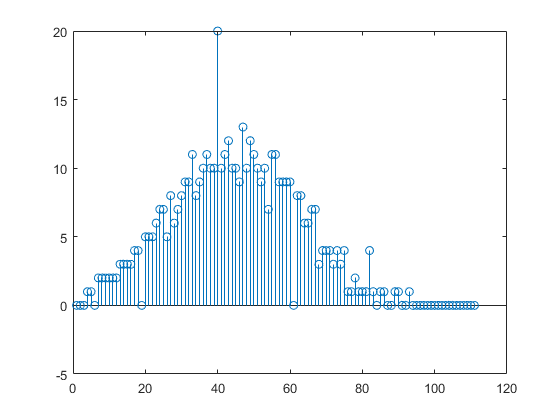

delay = dsp.Delay(16);
delayedGoldSeqB = delay(goldseqB());

y = xcorr(goldseqA(),delayedGoldSeqB);
stem(y)

[maxVal,maxPos] = max(y)

maxVal = 20

maxPos = 40

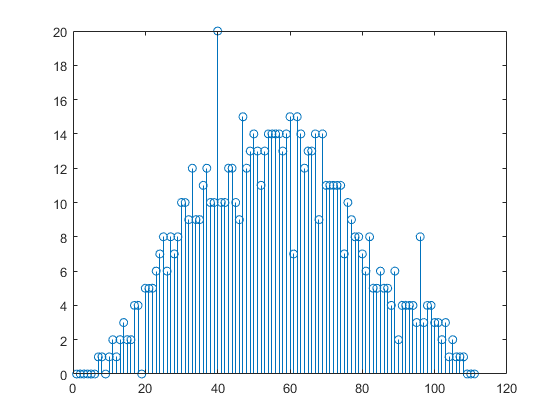

shiftedGoldSeqB = circshift(goldseqB(),16);
y = xcorr(goldseqA(),shiftedGoldSeqB);
stem(y)

[maxVal,maxPos] = max(y)

maxVal = 20

maxPos = 40